inv = "43";

M = 3;
D = 2;
R_sg = 0.4;
R_c = 1;
T_sg = 6;
T_c = 0.3;
T_mpc = 0.3;
K_mpc = 10;
K_dis = 0.4;

data_load = load("id_data\IBR="+inv+"_u=0.04.mat");
h = data_load.h

h = 0.0100


%Load train data
data_u1 = get_data("id_data\IBR="+inv+"_u=0.02.mat", inv);
data_u2 = get_data("id_data\IBR="+inv+"_u=0.03.mat", inv);
data_u3 = get_data("id_data\IBR="+inv+"_u=0.04.mat", inv);
data_u4 = get_data("id_data\IBR="+inv+"_u=-0.02.mat", inv);
data_u5 = get_data("id_data\IBR="+inv+"_u=-0.03.mat", inv);
data_u6 = get_data("id_data\IBR="+inv+"_u=-0.04.mat", inv);

%Use size 2 or 3 depending on which works better
data_d1 = get_data("id_data\loc=21_d=0.4.mat", inv);
data_d2 = get_data("id_data\loc=21_d=0.3.mat", inv);
data_d3 = get_data("id_data\loc=8_d=0.4.mat", inv);
data_d4 = get_data("id_data\loc=8_d=0.3.mat", inv);
data_d5 = get_data("id_data\loc=16_d=0.4.mat", inv);
data_d6 = get_data("id_data\loc=16_d=0.3.mat", inv);
data_d7 = get_data("id_data\loc=5_d=0.4.mat", inv);
data_d8 = get_data("id_data\loc=5_d=0.3.mat", inv);
data_d9 = get_data("id_data\loc=20_d=0.4.mat", inv);
data_d10 = get_data("id_data\loc=20_d=0.3.mat", inv);
data_d11 = get_data("id_data\loc=9_d=0.4.mat", inv);
data_d12 = get_data("id_data\loc=9_d=0.3.mat", inv);
data_d13 = get_data("id_data\loc=17_d=0.4.mat", inv);
data_d14 = get_data("id_data\loc=17_d=0.3.mat", inv);
data_d15 = get_data("id_data\loc=0_d=0.4.mat", inv);
data_d16 = get_data("id_data\loc=0_d=0.3.mat", inv);

data_train = merge(data_u1, data_u2, data_u3, data_u4, data_u5, data_u6, data_d1, data_d2, data_d3, data_d4, data_d5, data_d6, data_d7, data_d8, data_d9, data_d10, data_d11, data_d12, data_d13, data_d14, data_d15, data_d16);

params = {M; D; R_sg; R_c; T_sg; T_c; T_mpc; K_mpc; K_dis};
init_sys = idgrey(@ssm,params,'c');

opt = greyestOptions('SearchMethod','lsqnonlin','Display', 'on');
opt.SearchOptions.MaxIterations = 50;
power_sys = greyest(data_train, init_sys, opt);

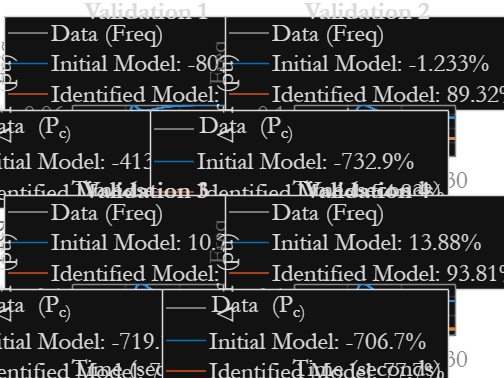

%Load validation data
data_val1 = get_data("id_data\IBR="+inv+"_u=0.03.mat", inv);
data_val2 = get_data("id_data\loc=5_d=0.4.mat", inv);
data_val3 = get_data("id_data\loc=8_d=0.4.mat", inv);
data_val4 = get_data("id_data\loc=16_d=0.4.mat", inv);

% Performance on validation data
f = figure;
subplot(2,2,1)
compare(data_val1,init_sys,power_sys);
xlabel('Time'),ylabel('\Delta f (pu)'),title('Validation 1')
legend({'Data','Initial Model','Identified Model'}, "Location","best")
grid on
subplot(2,2,2)
compare(data_val2,init_sys,power_sys);
xlabel('Time'),ylabel('\Delta f (pu)'),title('Validation 2')
legend({'Data','Initial Model','Identified Model'}, "Location","best")
grid on
subplot(2,2,3)
compare(data_val3,init_sys,power_sys);
xlabel('Time'),ylabel('\Delta f (pu)'),title('Validation 3')
legend({'Data','Initial Model','Identified Model'}, "Location","best")
grid on
subplot(2,2,4)
compare(data_val4,init_sys,power_sys);
xlabel('Time'),ylabel('\Delta f (pu)'),title('Validation 4')
legend({'Data','Initial Model','Identified Model'}, "Location","best")
grid on
fontsize(gcf, 25, "pixels")
fontname(gcf, "Garamond")
fig = gcf;
obj = findobj(fig,'Type','hggroup');
for idx = 1:numel(obj)
    for jdx = 1:numel(obj(idx).Children)
        obj(idx).Children(jdx).LineWidth = 2;
    end
end

% Identified physical values

params_id = getpar(power_sys, 'value');


id_M = params_id(1)

id_M = 2.4942

id_D = params_id(2)

id_D = 2.7192

id_R_sg = params_id(3)

id_R_sg = 0.2307

id_R_c = params_id(4)

id_R_c = 3.5151

id_T_sg = params_id(5)

id_T_sg = 5.7165

id_T_c = params_id(6)

id_T_c = 0.0075

id_T_mpc = params_id(7)

id_T_mpc = 0.7839

id_K_mpc = params_id(8)

id_K_mpc = 83.9281

id_K_dis = params_id(9)

id_K_dis = 0.4007


power_sysd = c2d(idss(power_sys), 0.1);

power_sys_ssm = idss(power_sys);
A_ssm = power_sys_ssm.A;
B_ssm = power_sys_ssm.B;
C_ssm = power_sys_ssm.C;
D_ssm = power_sys_ssm.D;

save("COI_models\DEC_model_inv="+inv+".mat",'A_ssm','B_ssm','C_ssm','D_ssm', 'id_M', 'id_D', 'id_R_sg', "id_R_c"	, "id_T_sg", "id_T_c", "id_T_mpc", 'id_K_mpc', "id_K_dis")
 

function [A,B,C,D] = ssm(M, D, R_sg, R_c, T_sg, T_c, T_mpc, K_mpc, K_dis, h)  
    A = [-D/M, 1/M, 1/M, 0;-1/(T_sg*R_sg), -1/T_sg, 0, 0; -1/(T_c*R_c), 0 , -1/T_c, K_mpc; 0, 0, 0, -1/T_mpc];
    Bd = [-K_dis;0;0;0];
    Bu = [0;0;0;1/T_mpc];
    B = [Bd, Bu];
    C = [1, 0, 0, 0; 0, 0, 1, 0];
    D = [0, 0; 0, 0];
end


function [data_loaded] = get_data(name, inv)
    S = load(name);
    h = S.h;
    t = S.t;
    d_1 = S.d_1 + S.d_2 + S.d_3 + S.d_4 + S.d_5 + S.d_6 + S.d_7 + S.d_8;

    u_field = ['Pmpc_' char(inv)];
    f_field = ['f_' char(inv)];
    Pe_field = ['Pe_' char(inv)];

    u_1  = S.(u_field);
    y_1  = S.(f_field);
    y_2  = S.(Pe_field);
    
    data_loaded = iddata([y_1, y_2], [d_1, u_1], h);
    data_loaded.OutputName = {'Freq', 'P_c'};
    data_loaded.InputName = {'P_dis', 'P_mpc'};
    data_loaded.Tstart = 0;
    data_loaded.TimeUnit = 's';
end
